# Tutorial for my Clewin-Matlab librerary

Guy 08/2020

## Installing the library

1. from the matlab command window in clewin, add the library folder to the matlab path by running something like:

lib_path = "Z:\Clewin-Matlab library";
addpath(lib_path);

the actual path might look different on your PC. 

2.  from the matlab command window in clewin, run:

clewin_setup;

3. from a seperate matlab window, make sure the library folder is in the path and then run:

matlab_setup;

this is necessary to be able to work from the matlab editor, and not only from clewin. some of the library's methods will cause matlab to crash unless you perform this step.  if you prefer to only work from inside Clewin then this step is not relevant.

4. add the folder(s) where you want to save your scripts to path. do it both from matlab and from the clewin matlab-command window.

now you can write and debug scripts that use the library in matlab editor, save them, and then call the saved sctiprs from Clewin.

## Introduction : how does clewin work with matlab

In clewin  you can draw polygons by running 

polygon(nodes);

where nodes is a Nx2 matrix of points (x,y).

for example, you can write

nodes = [0,0;0,1;1,0];
 polygon(nodes);

to get a right-angled triangle. when you run it in matlab it won't work because polygon() is not a matlab function (actually on my PC it causes matalb to crash), but if you followed the instructions in the previous section, then it should instead plot the polygon in the current figure window.

## Using the library

## Elements

the basic building blocks of the liberary are called elements.

### polygon elements: 

these are "atomic" elements in the sense that they are made of a single polygon.

for example, let's create the same right angle triangle but as an element:

nodes = [0,0;0,1;1,0];
triangle = polygon_element(nodes)

triangle =   polygon_element with properties:

    nodes: [3×2 double]
    ports: [1×1 struct]
    holes: {}


as you can see from the output, every polygon_element has 3 properties. nodes and ports are the important ones. 

nodes is just  the same Nx2 matrix of nodes:

triangle.nodes

ans =      0     0
     0     1
     1     0


ports are special points in the elemet's design that can be used to place it or to place other elements relative to it. I'll say more about ports later

### actions on elements

#### draw

 We have defined our triangle, but we still havn't drawn anything in clewin. for that we need to use the method draw(), like this:

triangle.draw();

which basically calls 

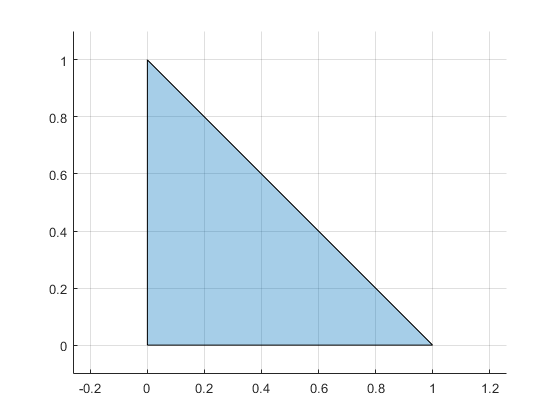

 polygon(triangle.nodes);

#### shift

moving the triangle to another point, say [10,-3]:

shift_vec = [10,-3];
triangle.shift(shift_vec);

check that the triangle has moved to the correct place by printing it's nodes: 

triangle.nodes

ans =     10    -3
    10    -2
    11    -3


note that by doing so we shift the actual triangle, and not create a new one. make sure you understand  the following example:

triangle = polygon_element(nodes); % redefining the same traignle
triangle_new = triangle.shift(shift_vec); % trying to define a new triangle which is a shifted vesion of triangle

triangle.nodes % check what happend to the original triangle

ans =     10    -3
    10    -2
    11    -3


the original triangle also moved. If we want to create a new triangle we can use the copy() method:

triangle = polygon_element(nodes); % defining the  traignle
triangle_new = triangle.copy().shift(shift_vec); % define a new triangle which is a shifted vesion of triangle


triangle.nodes % check what happend to the original triangle

ans =      0     0
     0     1
     1     0


triangle_new.nodes % check that we got what we wanted for the new triangle

ans =     10    -3
    10    -2
    11    -3


#### rotate

similarly, you can rotate the triangle by an arbitrary angle :

triangle.rotate(pi/2);

we have rotated the triangle about it's origin by default, but we can also rotate it around an arbitrary point:

triangle.rotate(pi/2, [-5,0]);
triangle.draw();

#### an arbitrary linear transformation

you can perform an arbitrary linear transformation on an element. the transformation is defined by a 2x2 matrix and an origin. By default, the origin is the origin of the element, but you can set it to something else. as an example, let's scale the triangle by 3 using a scaling matrix:

scale_mat = 3*eye(2); % a scaling matrix

triangle.apply_transformation(scale_mat);
triangle.draw();


note that since we did not supply an origin point, the scaling is with respect to the triangle's origin (the right angle vertex)

note that all the above methods (draw, shift, rotate, apply_transformation) and others, also return the object as an output, so you can write something like:

triangle.rotate(pi/3).shift([10,-14]).draw();

#### Invert

you can invert an element with the invert() method. it has one optional parameter that is the width of the boundary to add to the inverted shape, which is zero by default. for example:

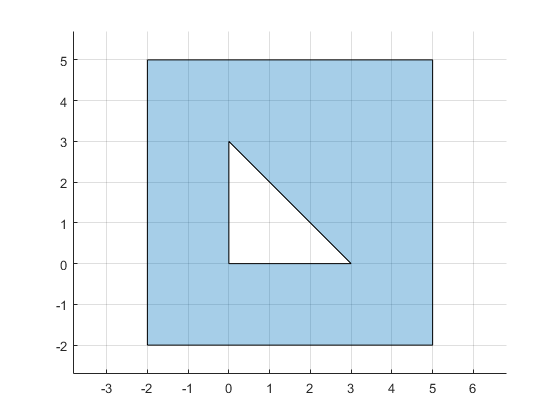

triangle.invert(2).draw(); 

in contrast to the other methods, invert does not change the element itself, but creates a new one. 

## simple coplanar elements

To exemplify the use of ports, I'll use two elements that are  built into the library: the coplanar line and the coplanar arc. First, let's introduce these elements: 

### coplanar line

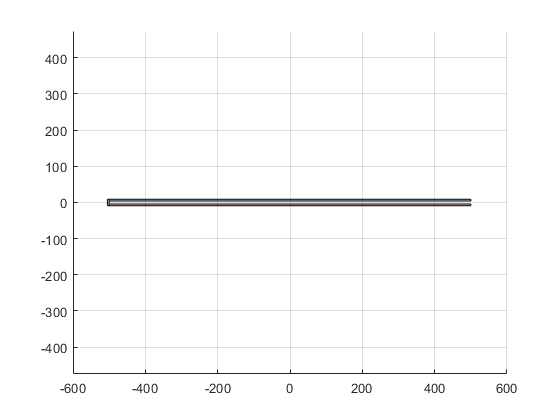

% define line properties
length = 1000; % length of line in micrones
trace_w = 8; % width of the centeral trace
gap_w = 5; % width of the gaps btw the trace and the ground
boundaries = [1,0]; % 0 is open and 1 is closed, so here I define an closed-open line

% define line and draw

my_line = coplanar_line(length, trace_w, gap_w, boundaries);
my_line.draw();

bounderies  is an optional arugument. by default the line is open-open.

### the coplanar arc

define a coplanar arc by running

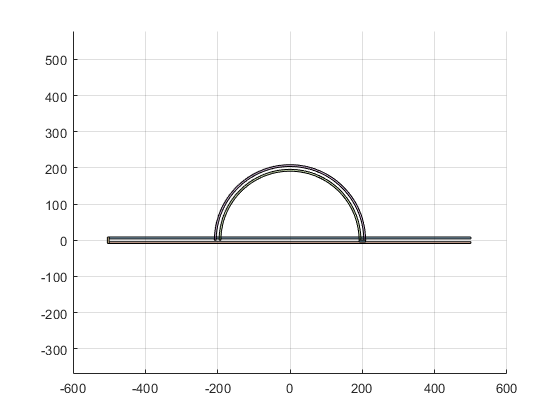

% arc properties
R = 200; %arc radius
angle = pi;  % arc angle, measured from positive x, counter clockwise
trace_w = 8;
gap_w = 5;
boundaries = [0,1]; % this is an optional parameter. see above.

% define and draw:

my_arc = coplanar_arc(R,angle,trace_w, gap_w, boundaries).draw();

the arc is drawn on top of the line from before (to get only the arc, use the clf command to clear the figure window), and both are centered at [0,0].

## ports and placing

let's say we want to connect the arc to the line  to get a "walking cane"   shape. For such porpuses each element comes with a set of ports - these are important points in the element design. for example, all elements have a port that is called "origin", and the coplanar_line element has two other ports labled "input" and "output":

my_line.ports

ans = struct with fields:
    origin: [0 0]
     input: [-500 0]
    output: [500 0]


similarly, for the arc:

my_arc.ports

ans = struct with fields:
    origin: [0 0]
    center: [0 0]
     input: [-200 2.4493e-14]
    output: [200 0]


when defining the ports for the various elements I generally followed the rule that input is in the left and output is in the right. for the coplanar_arc it means that the output is on the positive x direction, and the input is the other end of the arc

now let's create the walking cane: first rotate the line by 90 degrees:

my_line.rotate(pi/2);

then, place the input of the arc at the input of the line using the place method:

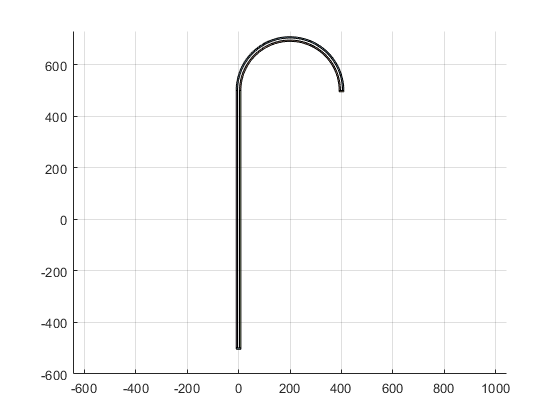

my_arc.place("input", my_line.ports.output); % placing the arc
 

% clear the figure window and draw:
clf;

my_arc.draw();
my_line.draw();

## defining new compound elements

let's say we want to define the walking cane as a new element. 

we have to use  matlab's syntax for class definition, in a seperate .m file:

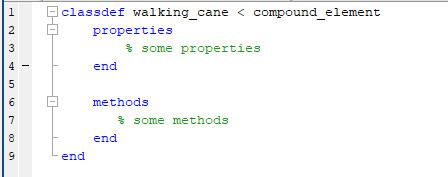

the < sign indicates that this class inherits all the methods and properties from the more abstract class compund_element. so when defining the new class, you don't have to implement all the existing methods like draw() or rotate().

### the compound_elements class

a compound element is an element that is built out of other elements. 

 the class compund_element has a property called sub_elements, which is a struct, whose fields are some elements.

 for example: even the simple coplanar line is actually a compound element that is made out of two rectangles:

my_line = coplanar_line(1000,8,5);
my_line.sub_elements

ans = struct with fields:
       top_rect: [1×1 rect]
    bottom_rect: [1×1 rect]


and similarly, a coplanar arc is made out of two arcs. 

### back to defining the walking_cane element:

some reasonable properties a cane should have are (total) length, radius of the arc, trace width and gap width:

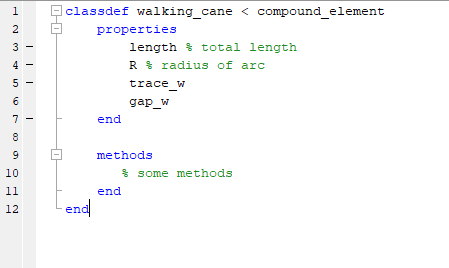

next, we have to define the class constructor - which is a special method that is called whenever an object is created:

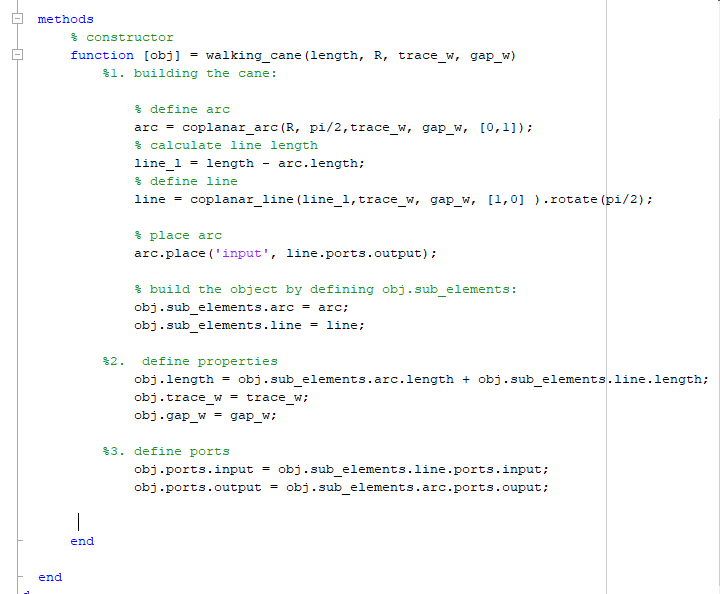

this constructor has three steps:

- building the walking cane by defining the cub elements

- defining the properties

- defining ports

"obj" is matlab's way to refer to the specific object being created by the constructor.  like "this" in c++.

now we can draw a walking cane with:

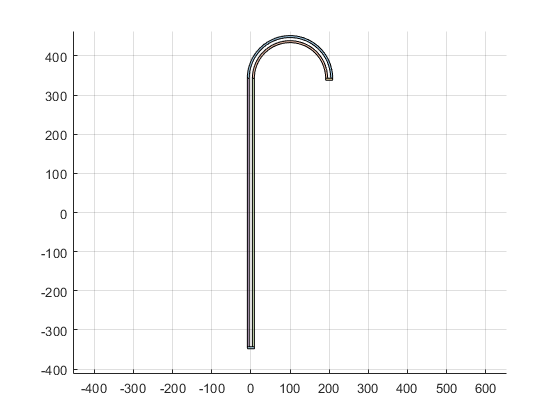

total_length = 1000;
R = 100;
trace_w = 8;
gap_w = 5;


clf
walking_cane(total_length,R,trace_w,gap_w).draw();

## defining a new array element

when defining a compound element we had to define each sub element and give it a name. this is not going to work when you want to create a large number of elements in a loop. for example, the coplanar_meander element is made out of many coplanar lines and arcs, and we can't give a name to each one. in such scenarios we have to use the class element_array. 

while the compound_element has a property sub_elements, which is a struct with elements in it's fields, the element_array class has a property called elements, which is a cell array of elements. check the structure of the class coplanar_meander:

trace_w = 8; gap_w = 5; segment_l = 300; distance = 100; N=7;

mea =   coplanar_meander with properties:

          length: 2.7996e+03
               N: 7
         trace_w: 8
           gap_w: 5
      boundaries: [0 0]
    sub_elements: [1×1 struct]
           ports: [1×1 struct]
           holes: {}



mea = coplanar_meander(trace_w, gap_w, segment_l, distance,N)

ans = struct with fields:
    lines: [1×1 element_array]
     arcs: [1×1 element_array]


first, it has a property called sub_elements - so it inherits from compound_element, but it's sub-elements are element_arrays:

mea.sub_elements

ans =   element_array with properties:

    elements: {[1×1 coplanar_line]  [1×1 coplanar_line]  [1×1 coplanar_line]  [1×1 coplanar_line]  [1×1 coplanar_line]  [1×1 coplanar_line]  [1×1 coplanar_line]}
       ports: [1×1 struct]
       holes: {}


one element_array for the lines anf one for the arcs. check for example what the element lines is made of:

mea.sub_elements.lines

ans = 1×7 cell array
    {1×1 coplanar_line}    {1×1 coplanar_line}    {1×1 coplanar_line}    {1×1 coplanar_line}    {1×1 coplanar_line}    {1×1 coplanar_line}    {1×1 coplanar_line}


it has a property  called elements, which is a cell-array of elements:

mea.sub_elements.lines.elements

ans = 1×8 cell array
    {1×1 coplanar_arc}    {1×1 coplanar_arc}    {1×1 coplanar_arc}    {1×1 coplanar_arc}    {1×1 coplanar_arc}    {1×1 coplanar_arc}    {1×1 coplanar_arc}    {1×1 coplanar_arc}


and similarly for the arcs:

mea.sub_elements.arcs.elements